## Adding Noise at Complex or Absolute (Magnitude)

Adding 10 dB of noise to both the complex signal and its absolute value (magnitude) will give resulting signals that are different because the phase information is not considered when only adding noise to the magnitude.

### IQ Sine Wave Example - Confidence Check

The complex IQ data is created by adding the sine wave to its imaginary part, resulting in a complex signal. The code then plots the real and imaginary parts separately and the complex IQ data in the complex plane. 

awgn function - a higher SNR value in the `awgn` function corresponds to less noise added to the signal, and the SNR(dB) value, when calculated, will be higher for a stronger signal relative to the noise. Because if you set SNR to a higher value, you are asking for a stronger signal relative to the noise in the output. Therefore, with a higher SNR value input to the awgn function, you can expect less noise added to the signal compared to a lower SNR setting.

### Parameters

Fs = 1000;    % Sampling frequency (Hz)
f = 10;      % Frequency of the sine wave (Hz)
t = 0:1/Fs:1-1/Fs; % Time vector

### Generate the sine wave

x = sin(2*pi*f*t);

### Create complex IQ data

IQ_data = x + 1i*x;

### Plot the real and imaginary parts

figure;

subplot(3,1,1);
plot(t, real(IQ_data), t, imag(IQ_data));
title('Real & Imaginary Parts');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, real(IQ_data));
title('Real Part');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, imag(IQ_data), 'r');
title('Imaginary Part');
xlabel('Time (s)');
ylabel('Amplitude');

### Apply awgn Function to Complex

In MATLAB, the `awgn` function has an optional input argument called 'measured', which, when set to 'on', adjusts the power of the input signal to account for the energy in the signal. This can be particularly useful when you have a signal with a varying amplitude.

If the 'measured' input argument is used, the `awgn` function will automatically scale the input signal to have a power equal to 1. This ensures that the specified SNR is applied correctly, regardless of the initial power of the input signal and the resulting SNR should be closer to the specified SNR, even if the amplitude of the original signal varies.

Noise wil be calculate with 'measured' on and off for comparision.

add_noise = 5   % SNR to be used by awgn function

add_noise = 5

Complex awgn 'measured'

IQ_data_plus_noise_measured = (awgn(IQ_data, add_noise, ...
    'measured')); % complex + awgn + measured

Complex awgn not 'measured'

IQ_data_plus_noise_not_measured = (awgn(IQ_data, add_noise)); % complex + awgn

% for i=1:length(IQ_data)
%     IQ_data_plus_noise = awgn(IQ_data, add_noise,...
%         'measured'); % complex + awgn
% end
% for i=1:length(IQ_data)
%     IQ_data_plus_noise_2 = awgn(IQ_data, add_noise); % complex + awgn
% end


### Apply awgn Function to Absolute

IQ_data_abs = abs(IQ_data);

Absolute awgn 'measured'

IQ_data_abs_plus_noise_measured = (awgn(IQ_data_abs, add_noise, ...
    'measured')); % abs + awgn + measured

Absolute awgn not 'measured'

IQ_data_abs_plus_noise_not_measured = (awgn(IQ_data_abs, add_noise)); % abs + awgn

### Plots of the Original and Noisy Signals 

### (Complex and Absolute, Measured and Not Measured)

Measured Plots

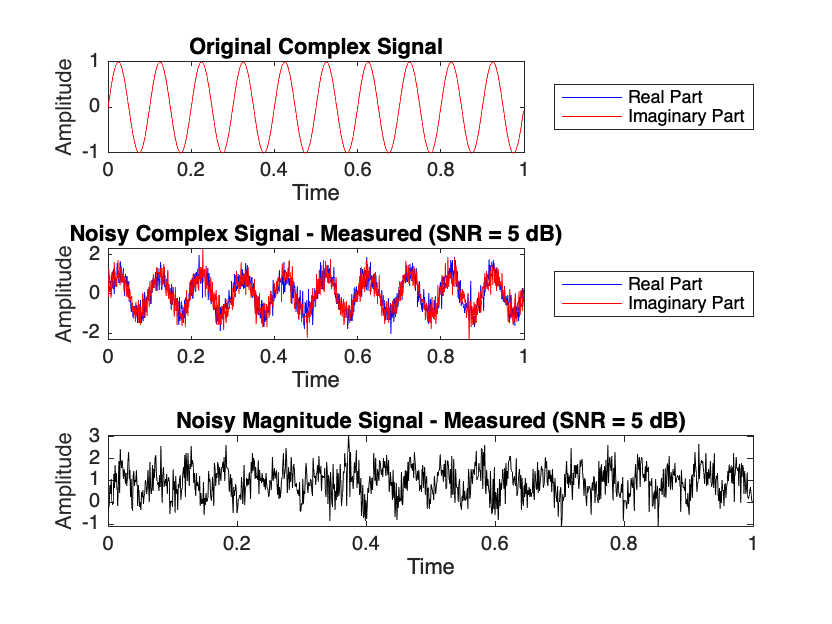

figure;
subplot(3,1,1);
plot(t, real(IQ_data), 'b', t, imag(IQ_data), 'r');
title('Original Complex Signal');
legend('Real Part', 'Imaginary Part');
xlabel('Time');
ylabel('Amplitude');
legend('Location', 'eastoutside');

subplot(3,1,2);
plot(t, real(IQ_data_plus_noise_measured), 'b', t, imag(IQ_data_plus_noise_measured), 'r');
title(['Noisy Complex Signal - Measured (SNR = ' num2str(add_noise) ' dB)']);
legend('Real Part', 'Imaginary Part');
xlabel('Time');
ylabel('Amplitude');
legend('Location', 'eastoutside');

subplot(3,1,3);
plot(t, IQ_data_abs_plus_noise_measured, 'k');
title(['Noisy Magnitude Signal - Measured (SNR = ' num2str(add_noise) ' dB)']);
xlabel('Time');
ylabel('Amplitude');

Not Measured Plots

figure;
subplot(3,1,1);
plot(t, real(IQ_data), 'b', t, imag(IQ_data), 'r');
title('Original Complex Signal');
legend('Real Part', 'Imaginary Part');
xlabel('Time');
ylabel('Amplitude');
legend('Location', 'eastoutside');

subplot(3,1,2);
plot(t, real(IQ_data_plus_noise_not_measured), 'b', t, imag(IQ_data_plus_noise_not_measured), 'r');
title(['Noisy Complex Signal - Not Measured (SNR = ' num2str(add_noise) ' dB)']);
legend('Real Part', 'Imaginary Part');
xlabel('Time');
ylabel('Amplitude');
legend('Location', 'eastoutside');

subplot(3,1,3);
plot(t, IQ_data_abs_plus_noise_not_measured, 'k');
title(['Noisy Magnitude Signal - Not Measured (SNR = ' num2str(add_noise) ' dB)']);
xlabel('Time');
ylabel('Amplitude');

### Calculate Mean Power

Calculate power of the original IQ data signal

P_IQ_data = mean(abs(IQ_data).^2)

P_IQ_data = 1

Calculate power of the added noise - Complex

P_IQ_complex_noise_measured = mean(abs(IQ_data_plus_noise_measured - IQ_data).^2)

P_IQ_complex_noise_measured = 0.3146

P_IQ_complex_noise_not_measured = mean(abs(IQ_data_plus_noise_not_measured - IQ_data).^2)

P_IQ_complex_noise_not_measured = 0.3244

Calculate power of the added noise - Absolute

P_IQ_abs_noise_measured = mean(abs(IQ_data_abs_plus_noise_measured - IQ_data_abs).^2)

P_IQ_abs_noise_measured = 0.3042

P_IQ_abs_noise_not_measured = mean(abs(IQ_data_abs_plus_noise_not_measured - IQ_data_abs).^2)

P_IQ_abs_noise_not_measured = 0.2827

Calculate SNR in dB

SNR_dB_complex_measured = 10 * log10(P_IQ_data / P_IQ_complex_noise_measured)

SNR_dB_complex_measured = 5.0224

SNR_dB_complex_not_measured = 10 * log10(P_IQ_data / P_IQ_complex_noise_not_measured)

SNR_dB_complex_not_measured = 4.8898

SNR_dB_abs_measured = 10 * log10(P_IQ_data / P_IQ_abs_noise_measured)

SNR_dB_abs_measured = 5.1687

SNR_dB_abs_not_measured = 10 * log10(P_IQ_data / P_IQ_abs_noise_not_measured)

SNR_dB_abs_not_measured = 5.4860

### Conclusion

To properly simulate a complex signal with a specific SNR, it's recommended to directly apply the awgn function to the complex signal - it results in a truer representation of the requested SNR value. Furthermore, it is recommended to set 'measured' when using the awgn function with the complex data expected to process. 